# Data Processing Procedure (DPP)

**Objective: **Hydrogen Deflagration Time-Series Analysis.

## **Procedure Steps**

## **Data Acquisition and Import**

### Collect Raw Data

Record the pressure data from the deflagration test at a known sampling rate and store all relevant metadata (e.g., test conditions, sensor specifications).

### Import into MATLAB

Load the raw time-series data (e.g., using load or CSV import) and verify the correct time alignment, sampling frequency, and units.

### Outcome

A raw pressure signal and associated metadata are available in MATLAB.

**Time-Frequency / Multiresolution Analysis **

- **Wavelet Decomposition: **Use MATLAB’sWavelet Analyzer or functions (e.g., ewt) to decompose the signal and examine the energy distribution across frequency bands.

- **Spectral Analysis:** Optionally, perform an FFT or generate a spectrogram to confirm the dominant frequencies and their temporal evolution.

- **Envelope Extraction (Optional): **Compute the Hilbert envelope or use the envelope function to highlight amplitude variations.

- **Outcome:** Identification of key frequency components and temporal localization of the deflagration event.

**Targeted Filtering / Smoothing (Informed by Analysis)**

- **Identify Frequency Ranges:** From the wavelet and spectral analysis, determine the frequency bands where the deflagration energy is concentrated and where noise is problematic.

- **Design Appropriate Filter:**

- **– Bandpass Filter: Apply if the event’s energy is confined to a specific band.**

- **– Notch Filter: Use to remove narrowband interference (e.g., 50/60 Hz).**

- **– Savitzly-Golay (SG) filters** [[1]](https://se.mathworks.com/help/signal/ug/design-and-analysis-of-savitzky-golay-filters.html#mw_rtc_DesignAndAnalysisOfSavitzkyGolayFiltersExample_M_5c01) are digital FIR lowpass filters that operate by moving least-squares polynomial fitting to input data samples within an interval. You can use SG filters to smooth or differentiate signal data, aiming to reduce noise while preserving the overall shape of the signal. This code creates and smooths a noisy Gaussian peak signal by performing SG filtering. SG filters are typically characterized by these parameters: *m*: Filter polynomial order, which is the degree of the lest-squares fitted polynomials used in the filter. ℓf: Frame length, which is the number of signal samples that form the interval width around the sample being filtered. Alternatively, the half-width interval *n*h can also characterize SG filters, where ℓf=2*n*h+1.

- **– Wavelet Thresholding: Consider removing noise-dominated detail levels.**

Reconstruct Signal with the desire mode.

- Verify that summing the MRA components results in perfect reconstruction of the signal.

- Verify energy preservation of the EWT analysis coefficients.

**Feature Extraction**

- **Peak Detection:** Use findpeaks or max(signal) to detect the maximum pressure, recording the peak amplitude and time-to-peak.

- **Impulse Calculation:** Integrate the baseline-corrected pressure signal over the duration of the event.

- **Additional Metrics:** Extract further features such as rise time, decay time, envelope area, or energy in specific wavelet sub-bands.

## Matlab Startup File

This m-File code prepare the enviroment to provide access to auxilliary files and sub-folders.

clear; clc; close all;
format short eng                              
[ProjectFolder,AuxFcn_GS] = AuxFcn_Matlab_Startup_File_001; % Project Startup Folder & Graphical Settings

## Import Signal Data

## Load "Raw" Signal

**Note: **Details on DAQ system setting are required, to check if any hardware filters has been used.

load('E2038.mat'); 

## Exploratory Data Analysis (EDA)

### **Visual Inspection**

Plot the raw signal to identify the main deflagration event, noise, and anomalies. Check for sensor clipping or saturation.

### **Descriptive Statistics**

Compute basic statistics (mean, variance, outliers) and estimate the event time window.

**Released Mass of Hydrogen [g]** 

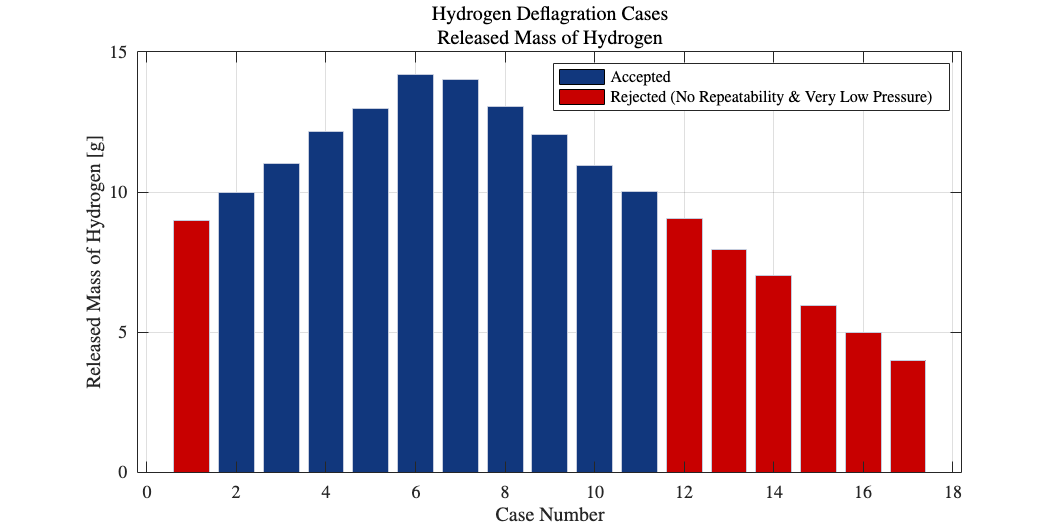

dataRMH = cases; % [g]
cases = 1:length(dataRMH);
% Define custom colors for boundary conditions
bar_colors = [AuxFcn_GS.LUBlue; AuxFcn_GS.darkred];
% Case Staus
Case_Staus = {'Accepted', 'Rejected (No Repeatability $\&$ Very Low Pressure)'};
% Create the bar plot with 'flat' FaceColor for per-bar coloring
figure;
x0=10;
y0=10;
width=25;
height=12.5;
set(gcf,'units','centimeters','position',[x0,y0,width,height])
barPlot = bar(cases, dataRMH, 'FaceColor', 'flat', 'EdgeColor', AuxFcn_GS.LUBlue_Light);

% Set default color for all bars
defaultColor = bar_colors(1,:); % Ensure this is an RGB triplet
barPlot.CData = repmat(defaultColor, length(dataRMH), 1);

% Define indices of bars to change and their new color
indicesToChange = [1,12:1:17]; % Example indices
newColor = bar_colors(2,:); % Example: red; replace with desired RGB triplet

% Update colors for selected bars
barPlot.CData(indicesToChange, :) = repmat(newColor, numel(indicesToChange), 1);

AuxFcn_Figure_Settings('Case Number','Released Mass of Hydrogen [g]',''...
    ,{'Hydrogen Deflagration Cases','Released Mass of Hydrogen'},12)

% Add legend manually using "dummy" bars
hold on;
legend_handles = gobjects(length(Case_Staus),1);  % Create empty objects for legend
for i = 1:length(Case_Staus)
    legend_handles(i) = bar(nan, nan, 'FaceColor', bar_colors(i, :)); % Create dummy bars for legend
end
legend(legend_handles, Case_Staus, 'Location', 'northeast');

**Raw Pressure Reading [bar]**

dataPraw = p; % [bar]
% Compute mean, max, and min across each test (column-wise)
meanValues = mean(dataPraw, 1); % Mean for each test
maxValues = max(dataPraw, [], 1); % Max for each test
minValues = min(dataPraw, [], 1); % Min for each test
% Create a test number column (1 to 17)
testNumbers = (1:length(cases))';
% Convert to table format
dataSummary = table(testNumbers,dataRMH', meanValues', maxValues', minValues', ...
    'VariableNames', {'Test Number','Released Mass of Hydrogen [g]', 'Mean [bar]', 'Max [bar]', 'Min [bar]'});
% Display the table
disp(dataSummary);

    Test Number    Released Mass of Hydrogen [g]    Mean [bar]    Max [bar]     Min [bar]
    ___________    _____________________________    __________    __________    _________

         1                      8.99                 -0.037241     -0.018687    -0.051562
         2                        10                 -0.030283    -0.0069375    -0.042313
         3                     11.03                 -0.030234       0.08575     -0.12812
         4                     12.16                 -0.016319      0.096437     -0.10237
         5                     12.99                 -0.056073      0.033938     -0.17606
         6                      14.2                -0.0088778       0.17475     -0.13594
         7                     14.01                 -0.043309        0.1665     -0.19669
         8         

**Baseline/Offset Assessment**

Identify any baseline offset and decide on necessary baseline correction.

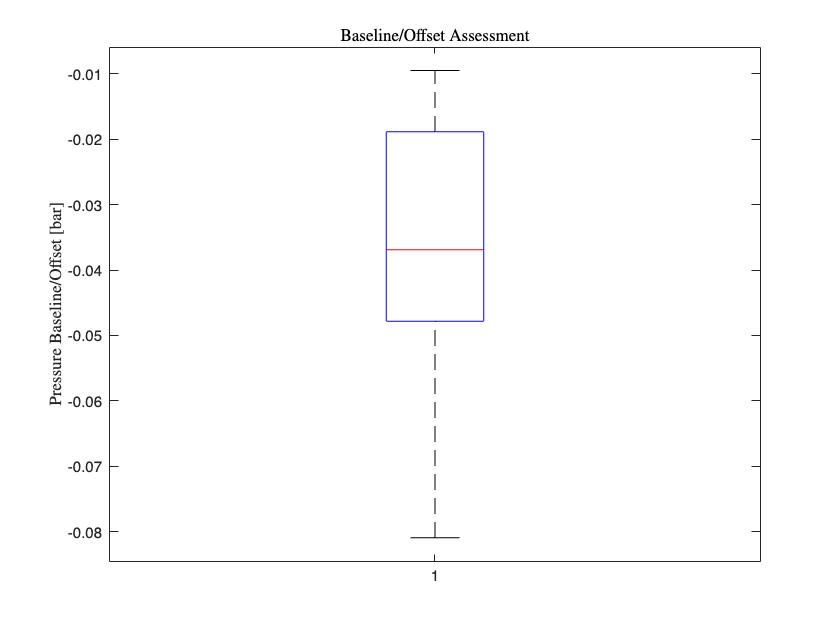

Fs = fs;             % Sampling frequency in Hz
t = (0:length(dataPraw)-1)'/Fs;
offset_Assessment = mean(p(1:100,:), 1);
figure;
boxplot(offset_Assessment);
ylabel('Pressure Baseline/Offset [bar]')
box on
title('Data Correction: Baseline/Offset Assessment')

## Signal Preprocessing

Pressure reading corrected (offset/baseline removed)

dataPoffsetCorrected = p - mean(p(1:100,:), 1);

## Selected Data for Analysis

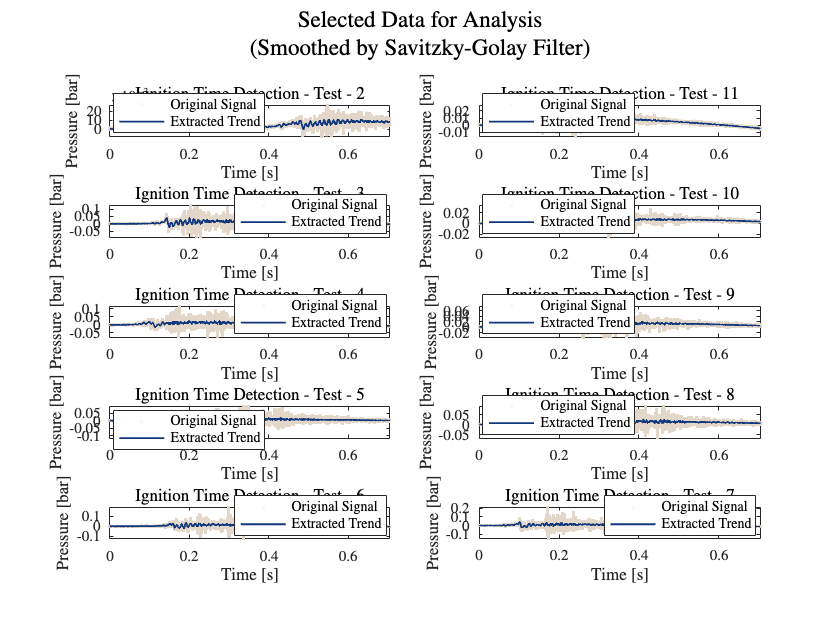

% Define number of tests based on available columns
selectedTests = [2,3,4,5,6,7,8,9,10,11];

% Define test pairs for subplot arrangement
test_pairs = [2, 11; 3, 10; 4, 9; 5, 8; 6, 7];  
rows = 5;
cols = 2;

figure;
for i = 1:size(test_pairs,1) % Loop over row pairs
    for j = 1:cols % Loop over columns
        test_index = test_pairs(i, j); % Get test number for subplot
        subplot(rows, cols, (i-1)*cols + j); % Arrange subplots
        
        % Smooth the pressure signal
        smoothed_pressure(:,test_index) = smooth(dataPoffsetCorrected(:,test_index), 9999, 'sgolay', 2);      
        
        % Scatter plot of original signal
        scatter(t, dataPoffsetCorrected(:, test_index), '.', ...
            'MarkerEdgeColor', AuxFcn_GS.LUCopper_Light, ...
            'MarkerEdgeAlpha', 0.2);
        hold on;
        
        % Plot extracted trend (using your blue color)
        plot(t, smoothed_pressure(:, test_index), 'Color', AuxFcn_GS.LUBlue, 'LineWidth', 1.2);
        
        % Title and labels
        title(['Ignition Time Detection - Test - ' num2str(test_index)]);
        xlabel('Time [s]');
        ylabel('Pressure [bar]');
        box on;
        legend('Original Signal', 'Extracted Trend', 'Location', 'best');
        axis tight;
        sgtitle({'Selected Data for Analysis','(Smoothed by Savitzky-Golay Filter)'})
       
    end

end
 hold off

## Time-Frequency / Multiresolution Analysis

### Empirical Wavelet Transform (EWT) [3]

The key thing to note is that similar to the wavelet and EMD decompositions, VMD segregates the three components of interest into completely separate modes or into a small number of adjacent modes. All three techniques allow you to visualize signal components on the same time scale as the original signal. There is a data-adaptive technique which actually constructs wavelet filters based on the frequency content of the data. This technique is the *empirical wavelet transform *(EWT) [3]. One of the major criticisms of EMD is that its definition is purely algorithmic. As a result, it is not readily amenable to mathematical analysis. EWT on the other hand actually constructs Meyer wavelets based on the frequency content of the analyzed signal. Accordingly, the results of EWT are amenable to mathematical analysis because the filters used in the analysis are available to the user. Repeat the analysis of the synthetic signal using the EWT.

#### Intrinsic Mode Functions (IMF)

% [mra_ewt,cfs,wfb,info] = ewt(dataPoffsetCorrected(:,1),MaxNumPeaks=10);
% helperMRAPlot(dataPoffsetCorrected(:,1),mra_ewt,t,"EWT","Empirical Wavelet Transform",[1 2 3 4 5])

#### PeakFrequenciesEmpirical Wavelet Transform (EWT) [3]

The key thing to note is that similar to the wavelet and EMD decompositions, VMD segregates the three components of interest into completely separate modes or into a small number of adjacent modes. All three techniques allow you to visualize signal components on the same time scale as the original signal. There is a data-adaptive technique which actually constructs wavelet filters based on the frequency content of the data. This technique is the *empirical wavelet transform *(EWT) [3]. One of the major criticisms of EMD is that its definition is purely algorithmic. As a result, it is not readily amenable to mathematical analysis. EWT on the other hand actually constructs Meyer wavelets based on the frequency content of the analyzed signal. Accordingly, the results of EWT are amenable to mathematical analysis because the filters used in the analysis are available to the user. Repeat the analysis of the synthetic signal using the EWT.

#### Intrinsic Mode Functions (IMF)

% [mra_ewt,cfs,wfb,info] = ewt(dataPoffsetCorrected(:,1),MaxNumPeaks=10);
% helperMRAPlot(dataPoffsetCorrected(:,1),mra_ewt,t,"EWT","Empirical Wavelet Transform",[1 2 3 4 5])

#### PeakFrequencies

PeakFrequencies — The peak normalized frequencies in cycles/sample identified in x as a column vector. For real-valued x, the frequencies are positive in the interval (0, ½) in decreasing order. For complex-valued x, the frequencies are ordered from (−½, ½). If PeakFrequencies is empty, ewt did not find any peaks and a default one-level discrete wavelet transform (DWT) subdivision is used.

% % Convert each PeakFrequencies from cycles/sample to Hz
% PeakFrequencies = Fs*info.PeakFrequencies;

#### FilterBank

FilterBank — A table with two variables: MRAComponent and Passbands. MRAComponent is the column index of the MRA component in mra. Passbands is a L-by-2 matrix where L is the number of MRA components. Each row of Passbands is the approximate frequency passband in **cycles/sample** for the corresponding EWT filter and MRA component.

% % Convert each passband from cycles/sample to Hz
% freqPassbands = info.FilterBank.Passbands * Fs;


Processing Test 2...


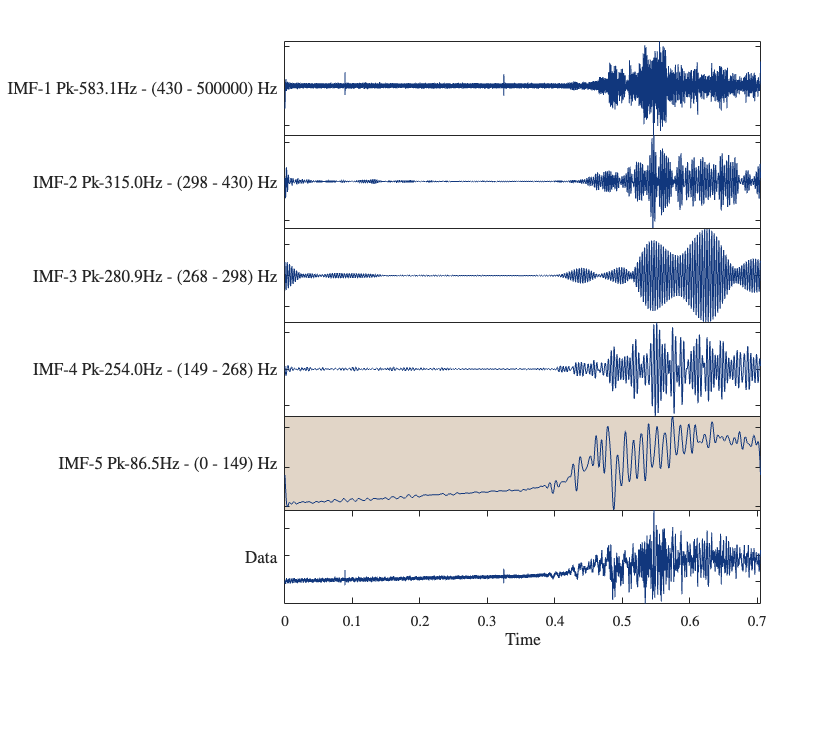

Processing Test 3...


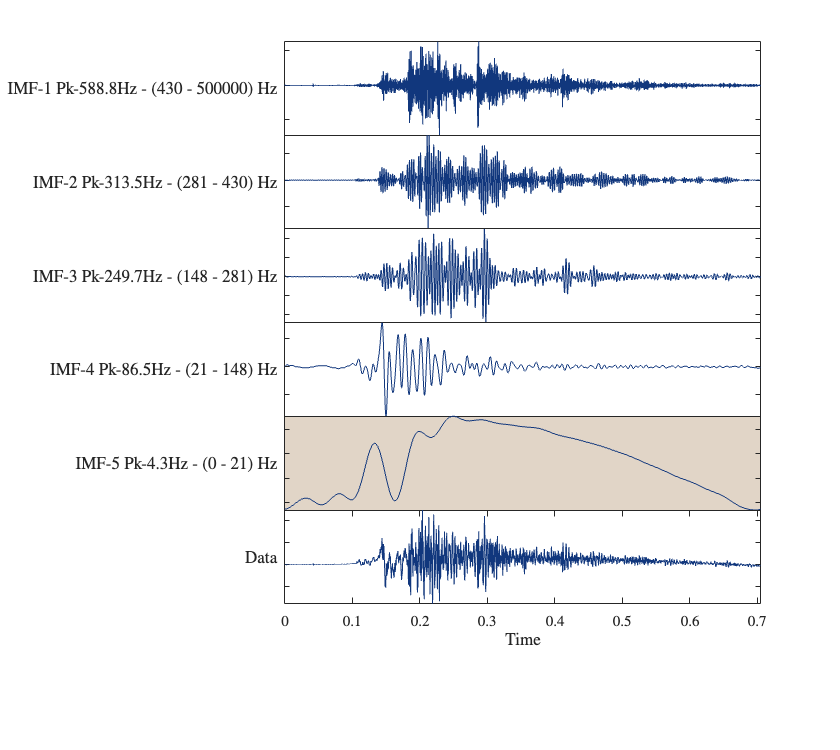

Processing Test 4...


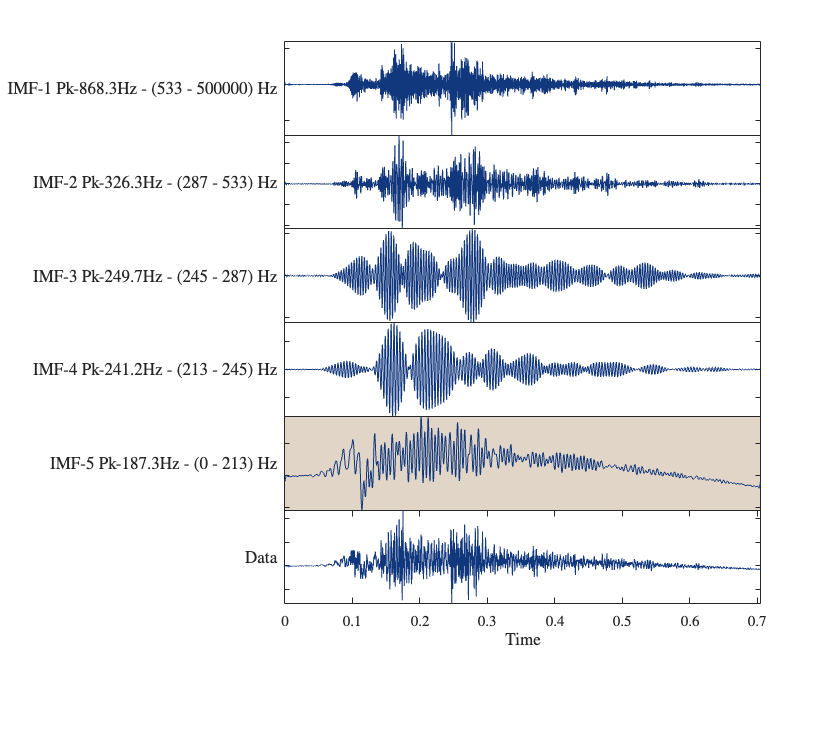

Processing Test 5...


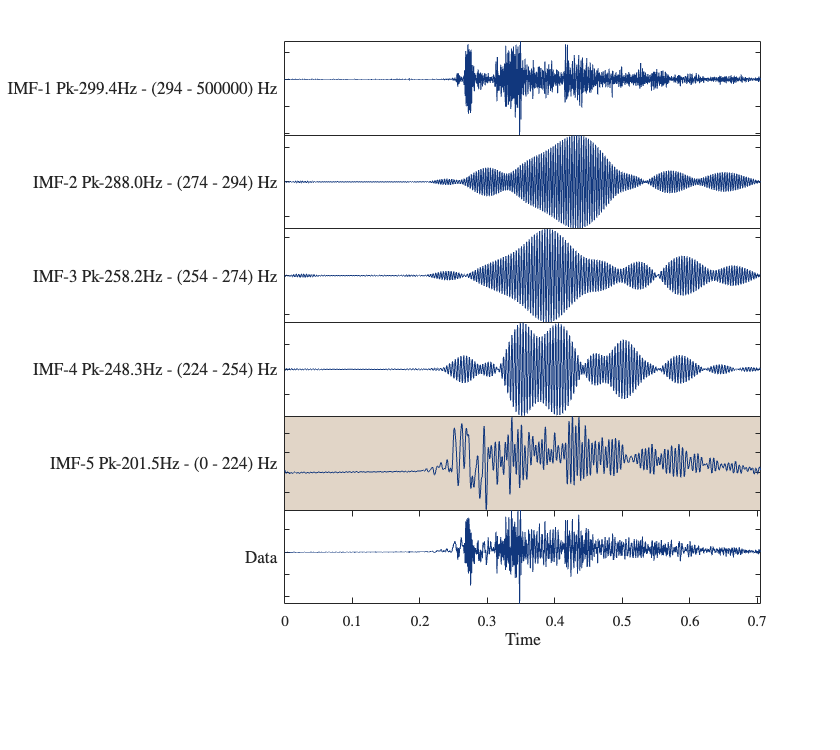

Processing Test 6...


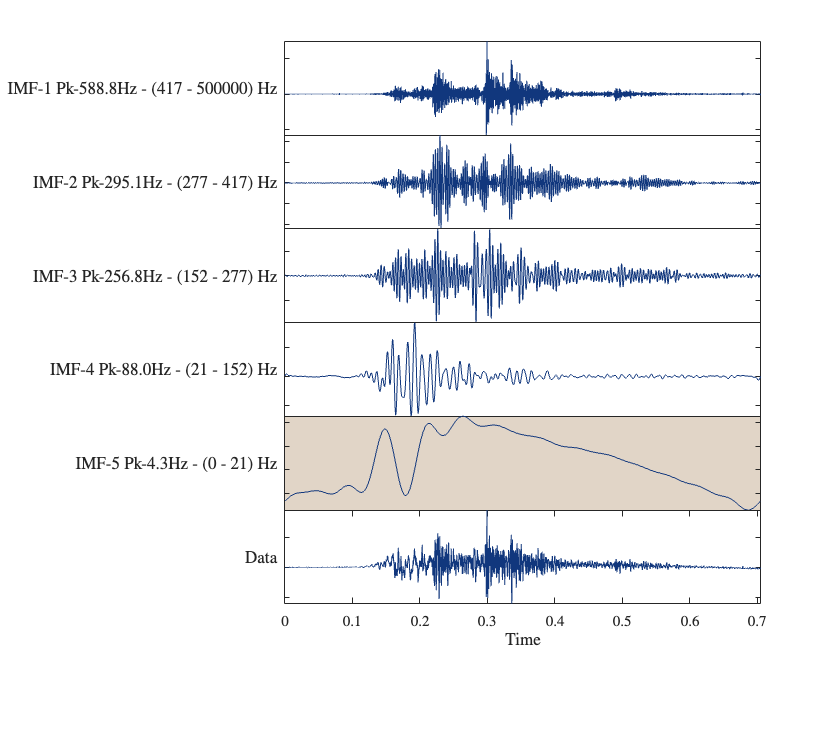

Processing Test 7...


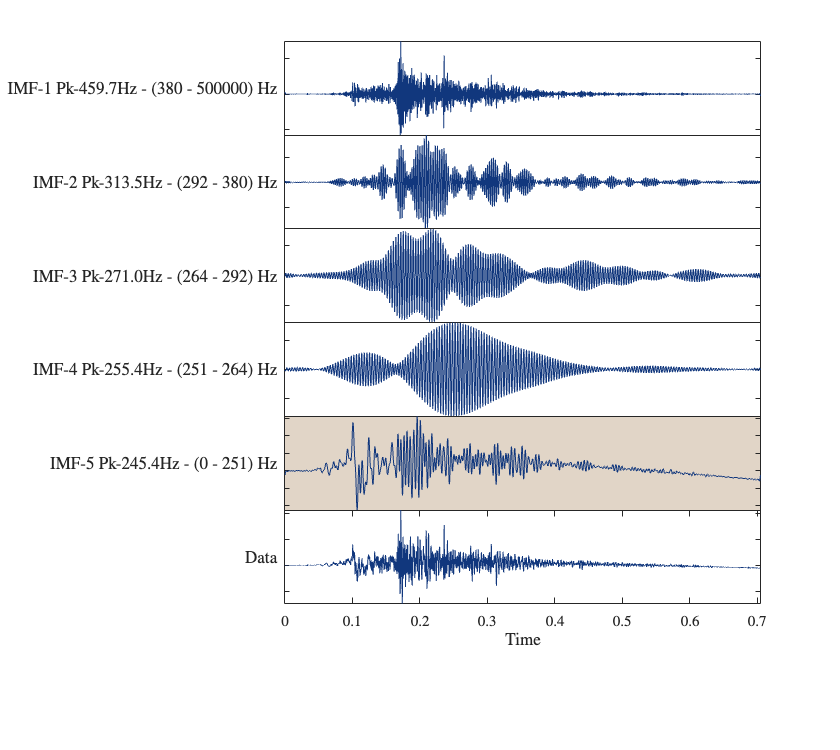

Processing Test 8...


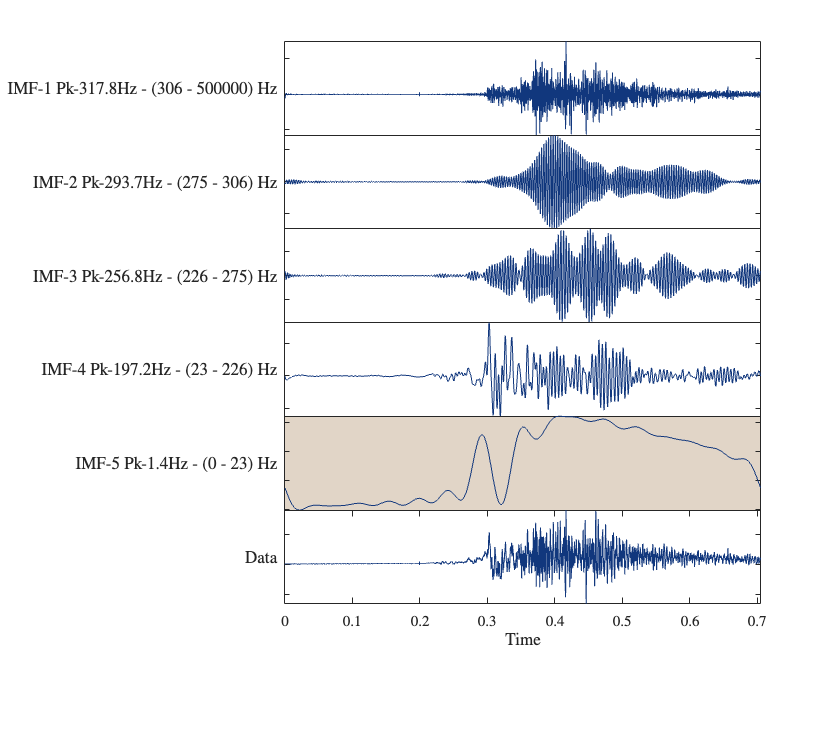

Processing Test 9...


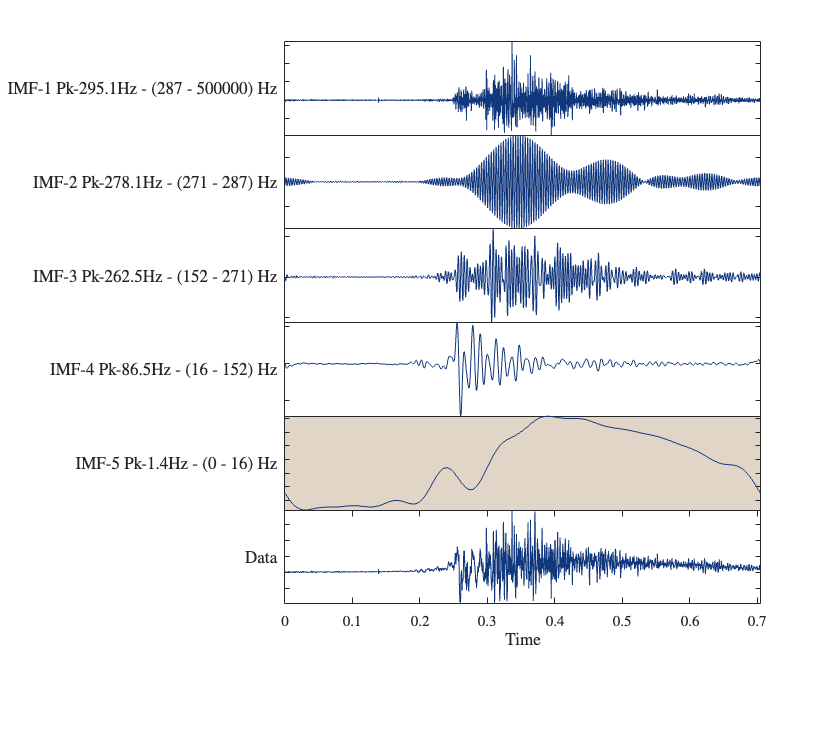

Processing Test 10...


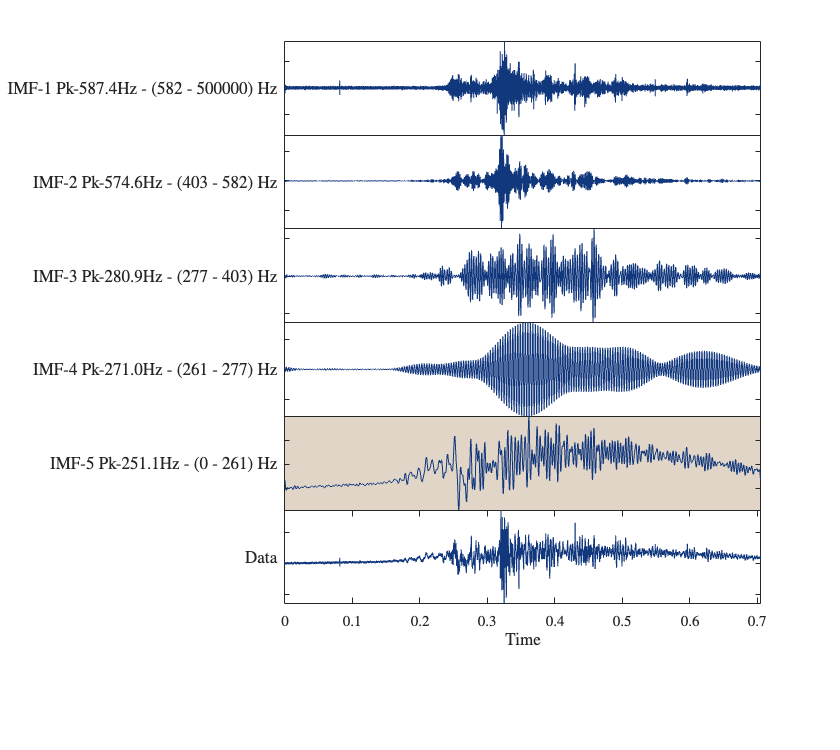

Processing Test 11...


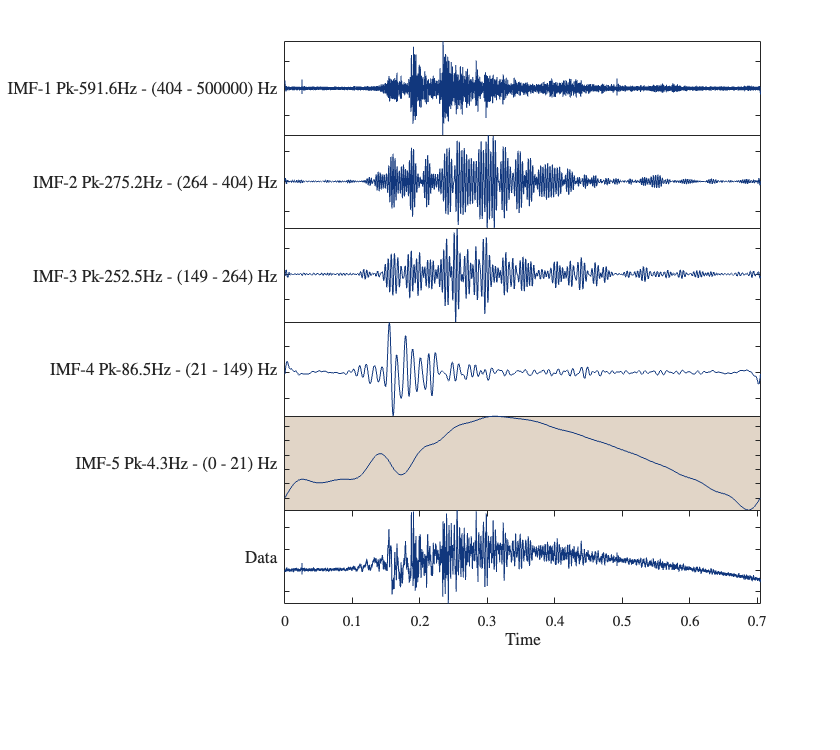

    Test Number    Mode Number    Peak Frequency (Hz)    Passband Start (Hz)    Passband End (Hz)
    ___________    ___________    ___________________    ___________________    _________________

         2              1                583.1                 429.88                 5e+05      
         2              2               314.96                 297.93                429.88      
         2              3               280.91                 268.14                297.93      
         2              4               253.95                 148.97                268.14      
         2              5               86.543                      0                148.97      
         3              1               588.78                 429.88                 5e+05      
         3              2               313.5

% selectedTests = [1 2 3 4 5 6 7 8 9 10 11 12]; % Choose which tests to analyze
% selectedTests = [2 3 4 5 6 7 8 9 10 11]; % Choose which tests to analyze
MaxNumPeaks = 5;
% HModes = [1 5];
HModes = MaxNumPeaks;
% Fig_width = 25;
% Fig_height = 1 * MaxNumPeaks + 1;
ewt_analysis(dataPoffsetCorrected, Fs, selectedTests, MaxNumPeaks,HModes);

## References

[1] Dragomiretskiy, Konstantin, and Dominique Zosso. “Variational Mode Decomposition.” *IEEE Transactions on Signal Processing* 62, no. 3 (February 2014): 531–44. [https://doi.org/10.1109/TSP.2013.2288675](https://doi.org/10.1109/TSP.2013.2288675).

[2] Flandrin, P., G. Rilling, and P. Goncalves. “Empirical Mode Decomposition as a Filter Bank.” *IEEE Signal Processing Letters* 11, no. 2 (February 2004): 112–14. [https://doi.org/10.1109/LSP.2003.821662](https://doi.org/10.1109/LSP.2003.821662).

[3] Giles, J. "Empirical wavelet transform", *IEEE Transactions on Signal Processing, *vol. 61, no. 16 (May 2013): 3999 - 4010. 

[4] Huang, Norden E., Zheng Shen, Steven R. Long, Manli C. Wu, Hsing H. Shih, Quanan Zheng, Nai-Chyuan Yen, Chi Chao Tung, and Henry H. Liu. “The Empirical Mode Decomposition and the Hilbert Spectrum for Nonlinear and Non-Stationary Time Series Analysis.” *Proceedings of the Royal Society of London. Series A: Mathematical, Physical and Engineering Sciences* 454, no. 1971 (March 8, 1998): 903–95. [https://doi.org/10.1098/rspa.1998.0193](https://doi.org/10.1098/rspa.1998.0193).

[5] Percival, Donald B., and Andrew T. Walden. *Wavelet Methods for Time Series Analysis*. Cambridge Series in Statistical and Probabilistic Mathematics. Cambridge ; New York: Cambridge University Press, 2000.

*Copyright 2019 The MathWorks, Inc.*